# 9.1 Adaptative Filtering

Alexandre Rey, MSE, MA-StatDig, 2022

clear;
rng default;

importedData=load('ex91_data.mat');
addpath('../functions/');

## Ex 9.1 : Adaptative Linear Prediction Using the LMS and NLMS Algorithm

Let $x[n]$ be a second order autoregressive process AR(2) that is generated according the difference equation:


$$\begin{array}{l}
x\left\lbrack n\right\rbrack =-a\left\lbrack 1\right\rbrack \cdot \;x\left\lbrack n-1\right\rbrack -a\left\lbrack 2\right\rbrack \cdot \;x\left\lbrack n-2\right\rbrack +v\left\lbrack n\right\rbrack \\
\;\;\;\;\;\;\;\;\;=1\ldotp 2728\cdot \;x\left\lbrack n-1\right\rbrack -0\ldotp 81\cdot \;x\left\lbrack n-2\right\rbrack +v\left\lbrack n\right\rbrack 
\end{array}$$


Where $v[n]$ is unit variance. So the coefficients are:


$$\begin{array}{l}
a\left\lbrack 1\right\rbrack =-1\ldotp 2728\\
a\left\lbrack 2\right\rbrack =\;0\ldotp 81
\end{array}$$


It gives a transfert function:


$$\frac{X\left(z\right)}{V\left(z\right)}=\frac{1}{1+a\left\lbrack 1\right\rbrack z^{-1} +a\left\lbrack 2\right\rbrack z^{-2} }=\frac{1}{1-1\ldotp 2728z^{-1} +0\ldotp 81z^{-2} }$$


The goal is to design a one step predictor using the adaptive LMS and NLMS algorithms and to compare it to a Wiener filter. This comparison to Wiener is possible because the process is stationary.

Below the scheme of the one step adaptive predictor. 

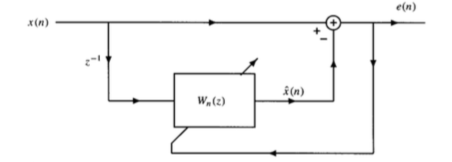

Therefore suppose we consider an adaptive linear predictor of the form:


$$\hat{x} \left\lbrack n\right\rbrack =w_{n\;} \left\lbrack 1\right\rbrack x\left\lbrack n-1\right\rbrack +w_{n\;} \left\lbrack 2\right\rbrack x\left\lbrack n-2\right\rbrack$$


Therefore, when $w_n[1]=1.2728$ and $w_n[2]=-0.81$, the eror becomes $e[n] = v[n]$ and the minimum square error is


$$\xi_{\min } =\sigma_v^2 =1$$


## Data Generation

### Parameter

Let's set the parameters:

b = 1;
a = [1, -1.2728, 0.81];
N = 1024;

disp(table(a,N));

               a                N  
    _______________________    ____

    1    -1.2728       0.81    1024



### Generation

Now the autoregressive process can be generated. The poles/zeros and the bode are also displayed.

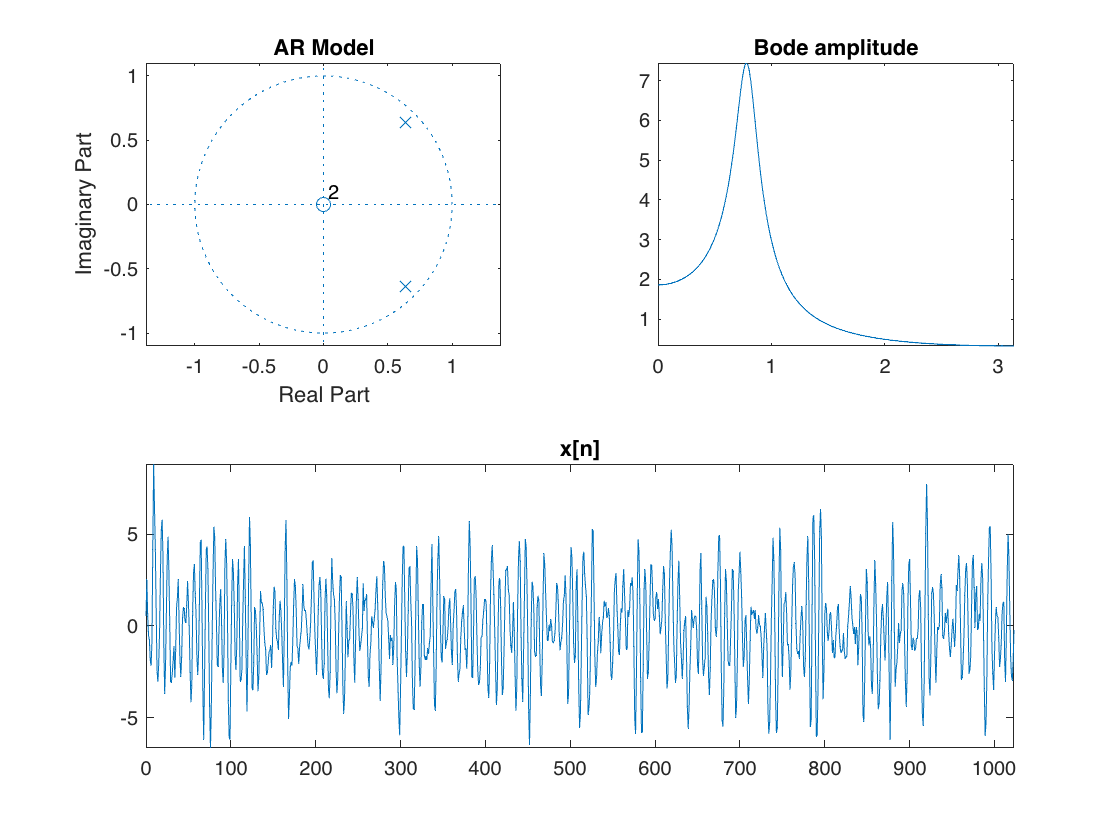

v = randn(1,N);
x = filter(b,a,v);
n = 0:N-1;

figure
tiledlayout(2,2);
nexttile;
    zplane(b, a);
    title('AR Model');
nexttile;
    [h, w] = freqz(b,a,1024);
    plot(w, abs(h));          % abs to get norm of complex values
    title('Bode amplitude');
    axis tight;
nexttile([1 2]);
    plot(n, x);
    xlim([min(n), max(n)]);
    title('x[n]');
    axis tight;

## Wiener-Hopf

As it is a WSS, the coefficients can be found with the Wiener-Hopf equations. The Wiener filter is designed with the estimation done on the data.

The optimum causal linear predictor for $x[n]$ is:


$$\hat{x} \left\lbrack n\right\rbrack =\;w\left\lbrack 1\right\rbrack x\left\lbrack n-1\right\rbrack +w\left\lbrack 2\right\rbrack x\left\lbrack n-2\right\rbrack$$



$$\hat{x} \left\lbrack n\right\rbrack =1\ldotp 2728x\left\lbrack n-1\right\rbrack -0\ldotp 81x\left\lbrack n-2\right\rbrack$$


Let's see what Wiener-Hopf provide:

### Design

It gives predictor coefficient very close of the auto-regressive coefficients.

p = 1; % filtre ordre 1

[w, E] = myWienerFIR(x(1:end-p), x(1+p:end), p)

w =     1.2874
   -0.8276


E = 0.9938

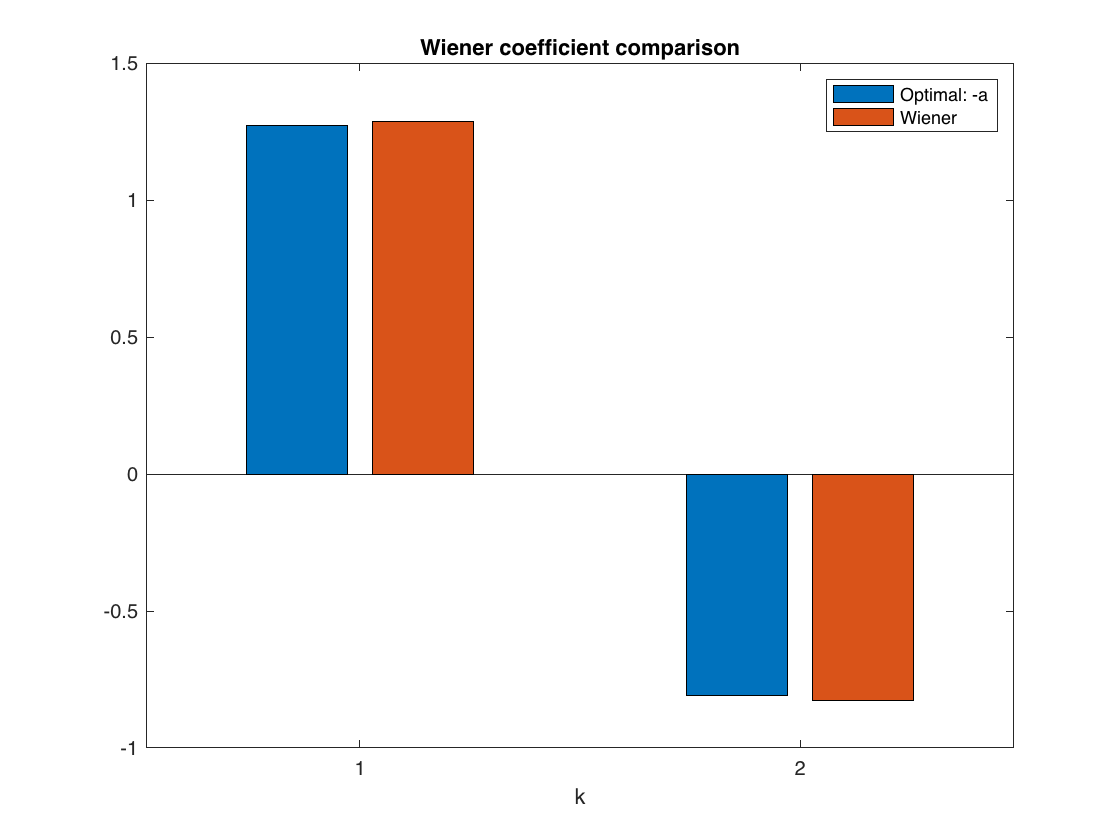

figure;
    bar([-a(2:3)', w]);
    title('Wiener coefficient comparison');
    legend('Optimal: -a', 'Wiener');
    xlabel('k');

    %axis tight;

### Prediction

If we apply the prediction and we compute the average squared error, it corresponds to the theory $\xi_{\min } =\sigma_v^2 =1$.

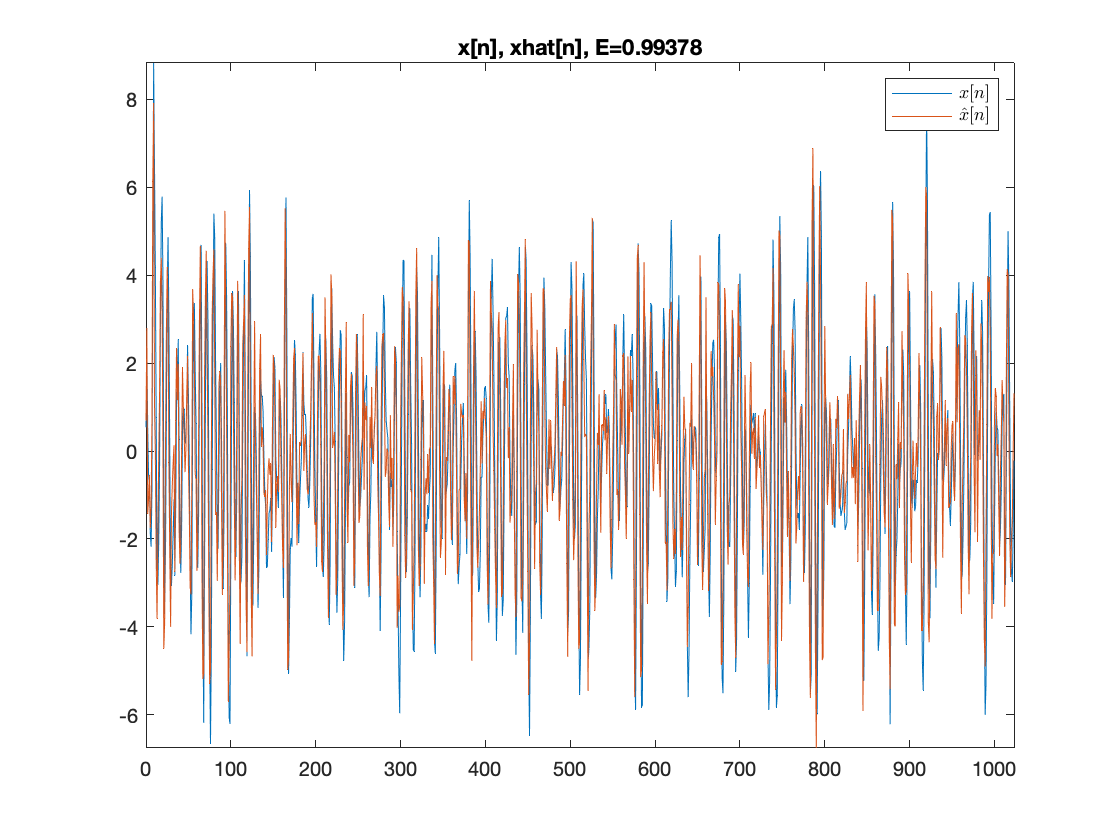

xhat = filter(w, 1, x);

figure;
    plot(n, x, ...
         n, xhat);
    title(['x[n], xhat[n], E=', num2str(E)]);
    legend('$x[n]$', '$\hat{x}[n]$', 'Interpreter', 'latex');
    %xlim([min(n), max(n)]);
    axis tight;

% Result: the Wiener-Hopf filters bad for non-WSS process.

## LMS

The predicitve parameters can be also found using the LMS algorithm.

With the LMS algorithm, the predictor coefficients $w_n[k]$ are updated as follows:


$$w_{n+1} \left\lbrack k\right\rbrack =w_n \left\lbrack k\right\rbrack +\mu \;e\left\lbrack n\right\rbrack x^* \left\lbrack n-k\right\rbrack$$


### Design

For the design, we will compare two different rate $\mu$. One too small ($\mu =5\cdot {10}^{-4}$) and one good ($\mu =1\cdot {10}^{-2}$). The following is showing the progression of the coefficient as well the squared error. To achieve that, you need to implement first the LMS algorithm (myLMS). Then, you can compute the estimated filter coefficient.

mu = [5E-4, 1E-2];      % rates
nord = 2;               % number of coefficient
p = nord-1;             % order

% input:        x = x(1:end-1)
% not useful to give the last value as there is nothing to predict from this one
% ideal output: d = x(1+nord:end)
% we cannot predict value before the delay due to the order of the filter

%             m rows
%             |                   n columns (nord coefficients)
%             |                   |     p page (tested mu)
%             |                   |     |
A_LMS = zeros(length(x(1:end-p)), nord, length(mu));
E_LMS = zeros(length(x(1:end-p)), 1,    length(mu));

for mu_i=1:length(mu)
    [A_LMS(:,:,mu_i), E_LMS(:,:,mu_i)] = myLMS(x(1:end-p), x(1+p:end), mu(mu_i), nord);
    disp(['LMS results (mu = ' num2str(mu(mu_i)) ') : ']);
    disp(A_LMS(end,:,mu_i));
end

LMS results (mu = 0.0005) : 


    0.8804   -0.4187



LMS results (mu = 0.01) : 


    1.2971   -0.7968



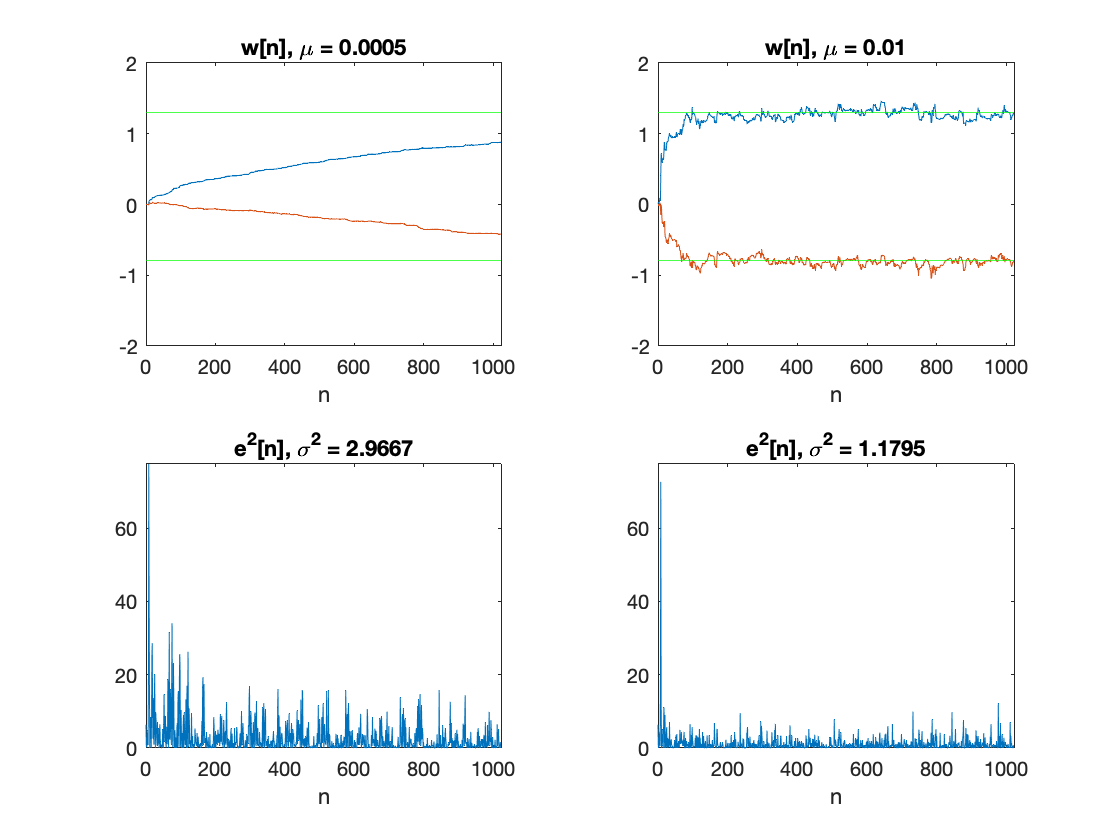

n_iter = n(1:end-p);

figure;
tiledlayout(2,2);
ax1=nexttile;
    mu_i=1;
    plot(n_iter, A_LMS(:,1,mu_i), ...
         n_iter, A_LMS(:,2,mu_i));
    yline([A_LMS(end,1,2) A_LMS(end,2,2)], 'g');
    title(['w[n], \mu = ' num2str(mu(mu_i))]);
    xlabel('n');
ax2=nexttile;
    mu_i=2;
    plot(n_iter, A_LMS(:,1,mu_i), ...
         n_iter, A_LMS(:,2,mu_i));
    yline([A_LMS(end,1,2) A_LMS(end,2,2)], 'g');
    title(['w[n], \mu = ' num2str(mu(mu_i))]);
    xlabel('n');
ax3=nexttile;
    mu_i=1;
    plot(n_iter, E_LMS(:,mu_i).^2);
    title(['e^2[n], \sigma^2 = ' num2str(var(E_LMS(:,mu_i)))]);
    xlabel('n');
ax4=nexttile;
    mu_i=2;
    plot(n_iter, E_LMS(:,mu_i).^2);
    title(['e^2[n], \sigma^2 = ' num2str(var(E_LMS(:,mu_i)))]);
    xlabel('n');
    
linkaxes([ax1 ax2 ax3 ax4], 'x');
linkaxes([ax1 ax2], 'y');
linkaxes([ax3 ax4], 'y');
ax1.YLim = [-2 2];
ax3.YLim = [0 max(E_LMS.^2,[],'all')];

The coefficients obtained are very close of the optimal coefficients after 1000 steps of adaptation for the the good $\mu$.

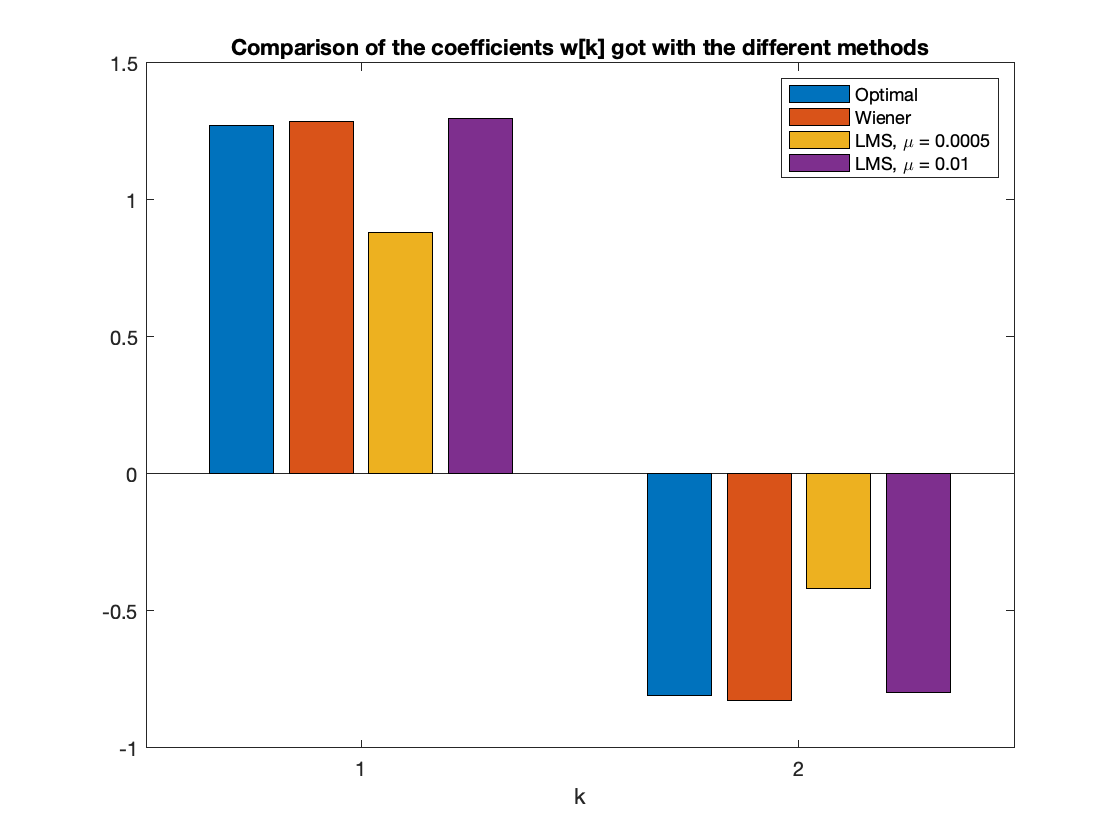

figure;
    bar([-a(2:3)', w, A_LMS(end,:,1)', A_LMS(end,:,2)']);
    title('Comparison of the coefficients w[k] got with the different methods');
    legend('Optimal', ...
           'Wiener', ...
           ['LMS, \mu = ' num2str(mu(1))], ...
           ['LMS, \mu = ' num2str(mu(2))]);
    xlabel('k');

### Performance surface

Finally, a performance surface is drawn with the two rates. It is showing the path realized on the error surface by the optimizer.

It can be observed that with the good rate, the optimizer is reaching the optimum coefficients and then oscillate there while with the slow rate,  the optimizer is never reaching it. To help you ot build the following figures, you can create a function *J = ComputeJFigure (x, a1, a2 )* which will compute the average squared error of the prediction for the given parameters.

w_res = 0.001;
w1_range =    0:w_res:2;
w2_range = -1.5:w_res:0;

J_LMS = zeros(length(w1_range), length(w2_range));

% for wi=1:length(w1_range)
%     for wj=1:length(w2_range)
%         J_LMS(wi, wj) = computeJFigure(x, w1_range(wi), w2_range(wj));
%     end
% end
% mu_i = 1;
% for i=nord:length(x)
%     J_iter(i) = computeJFigure(x, A_LMS(i,1,mu_i), A_LMS(i,2,mu_i));
% end

% figure;
%     subplot(2,2,1);
%         % TODO: optimize with fcontour(@computeJFigure)
%         contour(w1_range, w2_range, J_LMS');
%         hold on;
%         plot(A_LMS(:,1,mu_i), A_LMS(:,2,mu_i));
%         hold off;
%         xlabel('w_1');
%         ylabel('w_2');
%     subplot(2,2,2);
%         surf(w1_range, w2_range, J_LMS');
%         hold on;
%         plot3(A_LMS(nord:end,1,mu_i), A_LMS(nord:end,2,mu_i), J_iter');
%         hold off;
%         xlabel('w_1');
%         ylabel('w_2');

% for mu_i=1:length(mu)
%     figure;
%     subplot(2,2,1);
%         contour(A_LMS(:,1,mu_i), ...
%                 A_LMS(:,2,mu_i), ...
%                 E_LMS(:,mu_i));
% end

## NLMS

The predicitve parameters can be also found using the normalized LMS algorithm also called NLMS.

With the NLMS algorithm, the predictor coefficients $w_n[k]$ are updated as follows:


$$w_{n+1} \left\lbrack k\right\rbrack =w_n \left\lbrack k\right\rbrack +\beta \frac{x^* \left\lbrack n-k\right\rbrack }{\varepsilon +x^2 \left\lbrack n-1\right\rbrack +x^2 \left\lbrack n-2\right\rbrack }\;e\left\lbrack n\right\rbrack$$


### Design

Lets design the NLMS by using the normalized step sizes of $\beta=0.02$ and $\beta=0.005$, with $\epsilon=0.0001$.

beta=[0.02, 0.005];
epsilon=0.0001;
nord = 2;               % number of coefficient
p = nord-1;             % order

%              m rows
%              |                   n columns (nord coefficients)
%              |                   |     p page (tested mu)
%              |                   |     |
A_NLMS = zeros(length(x(1:end-p)), nord, length(beta));
E_NLMS = zeros(length(x(1:end-p)), 1,    length(beta));

for beta_i=1:length(beta)
    [A_NLMS(:,:,beta_i), E_NLMS(:,:,beta_i)] = myNLMS(x(1:end-p), x(1+p:end), beta(beta_i), nord, epsilon);
    disp(['NLMS results (beta = ' num2str(beta(beta_i)) ') : ']);
    disp(A_NLMS(end,:,beta_i));
end

NLMS results (beta = 0.02) : 


    1.2653   -0.8965



NLMS results (beta = 0.005) : 


    1.0517   -0.6513



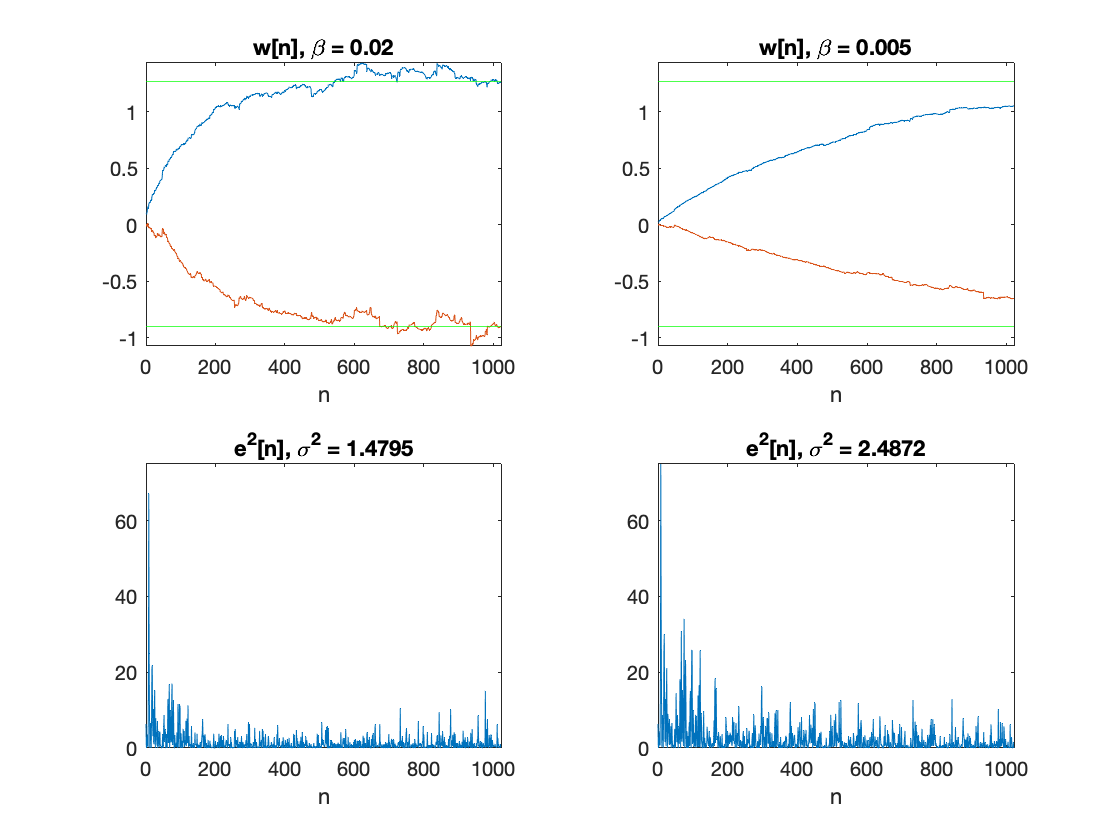

n_iter = n(1:end-p);

figure;
tiledlayout(2,2);
ax1=nexttile;
    beta_i=1;
    plot(n_iter, A_NLMS(:,1,beta_i), ...
         n_iter, A_NLMS(:,2,beta_i));
    yline([A_NLMS(end,1,1) A_NLMS(end,2,1)], 'g');
    title(['w[n], \beta = ' num2str(beta(beta_i))]);
    xlabel('n');
ax2=nexttile;
    beta_i=2;
    plot(n_iter, A_NLMS(:,1,beta_i), ...
         n_iter, A_NLMS(:,2,beta_i));
    yline([A_NLMS(end,1,1) A_NLMS(end,2,1)], 'g');
    title(['w[n], \beta = ' num2str(beta(beta_i))]);
    xlabel('n');
ax3=nexttile;
    beta_i=1;
    plot(n_iter, E_NLMS(:,beta_i).^2);
    title(['e^2[n], \sigma^2 = ' num2str(var(E_NLMS(:,beta_i)))]);
    xlabel('n');
ax4=nexttile;
    beta_i=2;
    plot(n_iter, E_NLMS(:,beta_i).^2);
    title(['e^2[n], \sigma^2 = ' num2str(var(E_NLMS(:,beta_i)))]);
    xlabel('n');
    
linkaxes([ax1 ax2 ax3 ax4], 'x');
linkaxes([ax1 ax2], 'y');
linkaxes([ax3 ax4], 'y');
ax1.YLim = [min(A_NLMS,[],'all') max(A_NLMS,[],'all')];
ax3.YLim = [0 max(E_NLMS.^2,[],'all')];

Finally, we can compare the found coefficients between all the methods. 

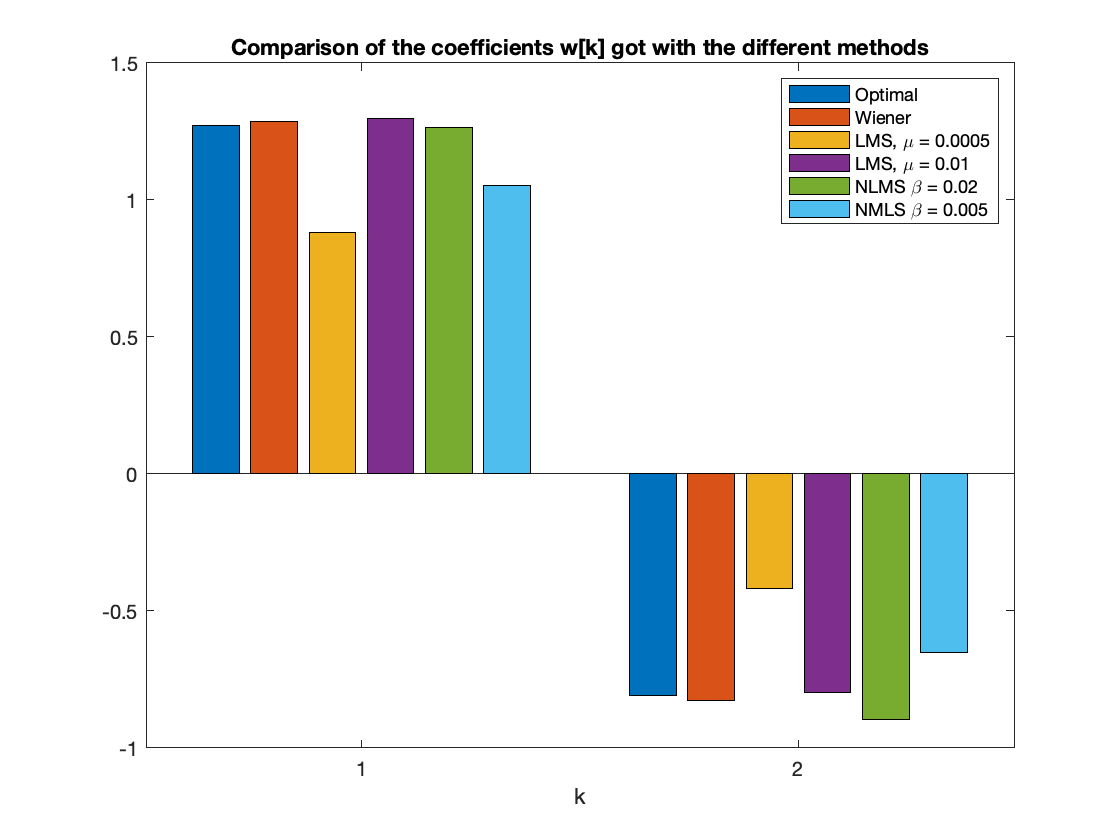

figure;
    bar([-a(2:3)', w, A_LMS(end,:,1)', A_LMS(end,:,2)', A_NLMS(end,:,1)', A_NLMS(end,:,2)']);
    title('Comparison of the coefficients w[k] got with the different methods');
    legend('Optimal', ...
           'Wiener', ...
           ['LMS, \mu = ' num2str(mu(1))], ...
           ['LMS, \mu = ' num2str(mu(2))], ...
           ['NLMS \beta = ' num2str(beta(1))], ...
           ['NMLS \beta = ' num2str(beta(2))]);
    xlabel('k');